# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Newstru\Newstru1\RawData'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 1;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = true;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false;                                                                  % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\Newstru\Newstru1\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Type = 'Manual';                                                                        % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {9};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {10};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [14 30 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq
Deci.DT.Block.Start   = {11};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.End     = {12};                                                                       % Cell Array of Markers for Block Starts
Deci.DT.Block.Markers = [];                                                                     % Num Array for each type of Block (if empty, Blocks are deliminated chronologically as -1,-2,..etc)

## 2. PreProcessing Steps

Deci.PP.HBP        = 1;                                                                         % Scalar,High-bandpass filter, in Hz.
Deci.PP.DownSample = [];                                                       % Downsample data
Deci.PP.More       = []   ;

## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5];                                                                % Critical Time Period for trial rejection (Respective to first Lock and Last Lock)
Deci.Art.muscle     = [];                                                                       % if empty, use default muscle parameters
Deci.Art.eog        = [];                                                                       % if empty, use default eog parameters
Deci.Art.PostICAbpf = [];                                                                       % Post ICA broadband pass filter, if desired

## 4. Analysis

#### General Set-Up

AllTrials;

#### Time-Frequency Analysis

Deci.Analysis.Freq.do            = true;
Deci_Hilbert;

#### Cross-Frequency Coupling

Deci.Analysis.CFC.do = false;
Deci.Analysis.CFC.chanlow =  {'FCz'};
Deci.Analysis.CFC.chanhigh = {'CP3'};
Deci.Analysis.CFC.latencyhigh = [-.2 1]; %no implementation yet to check for edge artifacts so be careful
Deci.Analysis.CFC.latencylow = [-.2 1];
Deci.Analysis.CFC.freqhigh = 'theta';
Deci.Analysis.CFC.freqlow = 'beta';

Deci.Analysis.CFC.timebin = 6;
Deci.Analysis.CFC.methods = {'mi' 'plv'};  % can only currently handle '' or 'mi'(pac)
Deci.Plot.CFC.errorbars = true ;

#### ERP

Deci.Analysis.ERP.do  = false;
Deci.Analysis.ERP.Toi = [-.5 1.5];

Extra

Deci.Analysis.Extra.QL.States = [20 21 23 24];
Deci.Analysis.Extra.QL.Actions = [31 32];
Deci.Analysis.Extra.QL.Reward  = [51 52];
Deci.Analysis.Extra.QL.Value  = {[20 10] [10 0] [0 -10] [-10 20]};

Deci.Analysis.Extra.do = true;
Deci.Analysis.Extra.list = [true];
Deci.Analysis.Extra.Functions = {'QL'};
Deci.Analysis.Extra.Params = {{Deci.Analysis.Extra.QL}};

## 5. Plotting

Deci.Plot.Version = ['C:\Users\User\Desktop\John\Newstru\Newstru1\' 'ProcessedData'];
Deci.Plot.Lock = 'Fdb Onset';
Deci.Plot.GrandAverage = true;
Deci.Plot.FreqYScale = 'linear';


#### Conditions

Deci.Plot.IndexTitle = {'Opt CD Corr' 'Opt GH Corr' ...
                        'Opt AB Inc'  'Opt EF Inc'};

Deci.Plot.Math         = {'[x1 + x3]/2' '[x2 + x4]/2' '[x5 - x6]' '[x1 + x2]/2' '[x3 + x4]/2' '[x8 - x9]'};           % Condition Math done after Bsl, Condition Indexes are appended on.
Deci.Plot.Draw         = {[1 2 3 4] [5 6] [7] [8 9] [10]};                   % Cell array of Condition Index for each figure
Deci.Plot.Figures      = [true false false false false];                             % Which figure to plot currently
Deci.Plot.Title        = {'All Opt 10 trials' 'R v P' 'R - P' '+ v -' '+ - -'};          % Title for each figure
Deci.Plot.Subtitle     = {{'+R' '+P' '-R' '-P'} {'R' 'P'} {'R - P'} {'+' '-'} {'+ - -'}};     % Cell array of strings of subtitles for each Condition

#### Time-Frequency

Deci.Plot.Freq.Foi     = [4 8];                   % Frequency of Interest
Deci.Plot.Freq.Toi     = [-.5 1.5];                   % Time of Interest
Deci.Plot.Freq.Channel = {'FCz'};                   % Channel of Interest
Deci.Plot.Freq.Type    = 'TotalPower';                   % Use 'TotalPower','ITPC' or 'EvokedPower' (Currently Unavailable)
Deci.Plot.Freq.Bsl     = [-.5 -.2];                             % Baseline Correction Time
Deci.Plot.Freq.Topo    =false;
Deci.Plot.Freq.Square  =true;
Deci.Plot.Freq.Wire    =false;

**CFC**

%Currently Unavailable
Deci.Plot.CFC.Topo = true;
Deci.Plot.CFC.Square = true;
Deci.Plot.CFC.Hist = true;
Deci.Plot.CFC.Wire = true;
Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest

**ERP**

Deci.Plot.ERP.Toi = [0 .8];
Deci.Plot.ERP.Channel = {'FCz'};
Deci.Plot.ERP.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.ERP.Topo =true;
Deci.Plot.ERP.Wires =true;

#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Total = {[1:16] [1:16]};
Deci.Plot.Behv.Acc.Subtotal = {[1:8] [9:16]};
Deci.Plot.Behv.Acc.Title = {'All Trials Percent' 'All Trials Percent'};
Deci.Plot.Behv.Acc.Subtitle = {'Opt Percent' 'Wst Percent'};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =true;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = true;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'maxlength:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  false;

Deci.Plot.Behv.RT.Draw = {[1:8] [9:16]};
Deci.Plot.Behv.RT.Title = {'All Trials RT' 'All Trials Percent'};
Deci.Plot.Behv.RT.Subtitle = {'Opt' 'Worst'};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

** Extra**

Deci.Plot.Extra.List = false;
Deci.Plot.Extra.Functions = {'QL'};
Deci.Plot.Extra.Params = {{}};

Options

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;
Deci.Run.Extra = false;

## ** 6. Run**

----------------------
Starting Artifactor
searching for artifacts in 62 channels
searching in trial 480 from 480



detected 135 artifacts
the call to "ft_artifact_zvalue" took 93 seconds
searching for artifacts in 4 channels
searching in trial 480 from 480



detected 16 artifacts
the call to "ft_artifact_zvalue" took 14 seconds
detected 135 muscle artifacts
detected  16 eog artifacts
rejected   73 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained   33 trials with artifacts outside critical window
resulting 407 trials
the input is raw data with 62 channels and 480 trials


the call to "ft_redefinetrial" took 9 seconds
the call to "ft_rejectartifact" took 10 seconds
the input is raw data with 62 channels and 407 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 407 trials


showing a summary of the data for all channels and trials


computing metric [---|                                                     ]computing metric [--------/                                                ]computing metric [---------------                                          ]computing metric [-------------------\                                     ]computing metric [-------------------------|                               ]computing metric [-------------------------------/                         ]computing metric [--------------------------------------                   ]computing metric [------------------------------------------\              ]computing metric [------------------------------------------------|        ]computing metric [------------------------------------------------------/  ]computing metric [---------------------------------------------------------]


367 trials marked as GOOD, 40 trials marked as BAD
62 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 2, 24, 50, 51, 58, 61, 71, 76, 78, 85, 87, 94, 102, 107, 112, 115, 116, 125, 128, 154, 162, 165, 173, 189, 201, 206, 208, 213, 223, 236, 251, 259, 265, 281, 282, 302, 309, 321, 370, 376
the call to "ft_rejectvisual" took 628 seconds
the input is raw data with 62 channels and 367 trials


baseline correcting data 
scaling data with 1 over 94.001076
concatenating data...............................................................................................................................................................................................................................................................................................................................................................................
concatenated data matrix size 62x1805508
starting decomposition using runica

Input data size [20,1805508] = 20 channels, 1805508 frames/nAfter PCA dimension reduction,
  finding 20 ICA components using logistic ICA.
Decomposing 4513 frames per ICA weight ((400)^2 = 1805508 weights, Initial learning rate will be 0.001, block size 73.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will 

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds


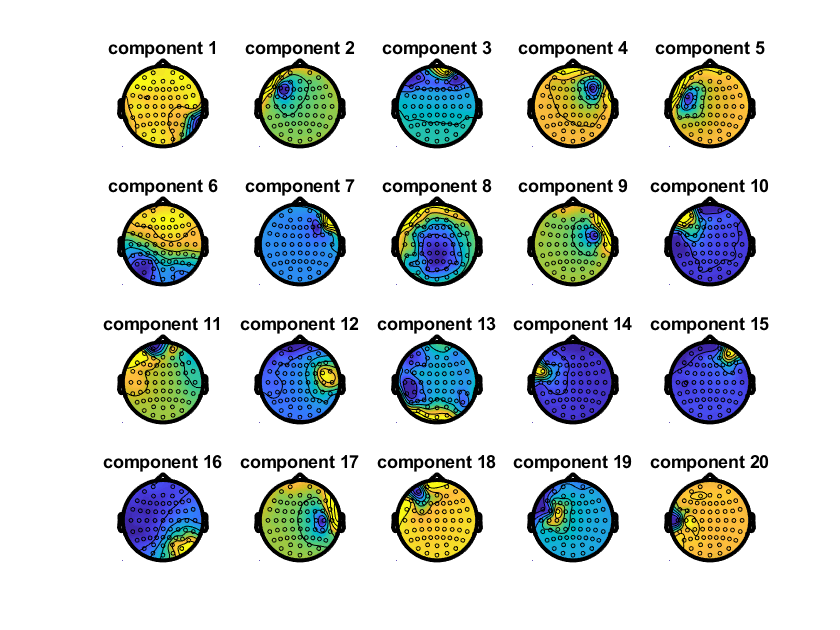

the call to "ft_topoplotIC" took 7 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the input is component data with 20 components and 62 original channels
the input is raw data with 20 channels and 480 trials
detected   0 visual artifacts


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



removing 2 components
keeping 18 components
not applying the backprojection matrix to the sensor description
the call to "ft_rejectcomponent" took 1 seconds


detected 132 artifacts
the call to "ft_artifact_zvalue" took 87 seconds


detected 60 artifacts
the call to "ft_artifact_zvalue" took 14 seconds
detected 132 muscle artifacts
detected  60 eog artifacts
rejected   84 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained   37 trials with artifacts outside critical window
resulting 396 trials
the input is raw data with 62 channels and 480 trials


the call to "ft_redefinetrial" took 10 seconds
the call to "ft_rejectartifact" took 10 seconds


ans =        -2005       -3302       -4983
       -2006       -2819       -4932
       -2004       -3067       -4887
       -2005       -3125       -5011
       -2006       -2978       -4997
       -2007       -3161       -5000
       -2005       -2955       -4968
       -2004       -3057       -4964
       -2003       -3077       -5001
       -2004       -2868       -4898


ans =        -2005       -3302       -4983
       -2006       -2819       -4932
       -2004       -3067       -4887
       -2005       -3125       -5011
       -2006       -2978       -4997
       -2007       -3161       -5000
       -2005       -2955       -4968
       -2004       -3057       -4964
       -2003       -3077       -5001
       -2004       -2868       -4898


ans = 0

ans = 0

ans = 456


Deci_Backend(Deci);